clc
clear all
close all

**Read Prices**

load myPrice_dt.mat
load array_prices

**Selection of a subset of Dates**

start_dt = datetime('01/01/2021', 'InputFormat', 'dd/MM/yyyy');
end_dt = datetime('01/01/2022', 'InputFormat', 'dd/MM/yyyy');

rng = timerange(start_dt, end_dt, 'closed');
subsample = myPrice_dt(rng, :);
prices_val = subsample.Variables;
dates_ = subsample.Time;

**Compute Moments**

LogRet = tick2ret(prices_val, 'Method', 'continuous');
ExpRet = mean(LogRet);
CovMatrix = cov(LogRet);

**Var - Historical Simulation - h = 1**

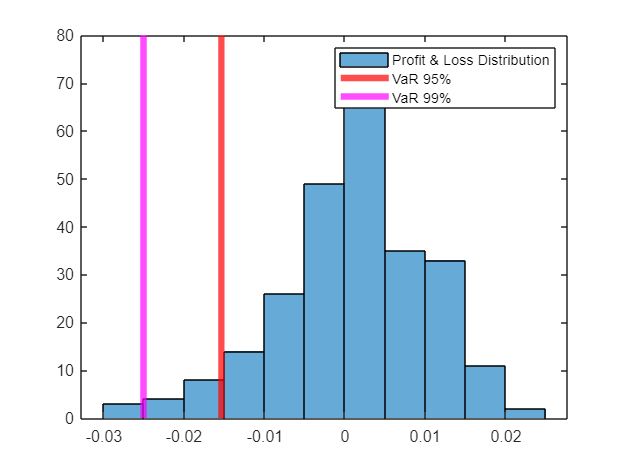

weightsEW = ones(15,1) .* 1/15;
ConfLevel = [0.95, 0.99];
pRet = weightsEW' * LogRet';

VaR_95 = quantile(pRet, 1-ConfLevel(1,1));
VaR_99 = quantile(pRet, 1-ConfLevel(1,2));

%Expeted Shortfall 
ES_95 = mean(pRet(pRet<VaR_95));
ES_99 = mean(pRet(pRet<VaR_99));

%Plot
figure;
histogram(pRet);
hold on
xline(VaR_95, 'LineWidth', 4, 'Color','r')
xline(VaR_99, 'LineWidth', 4, 'Color','m')
legend('Profit & Loss Distribution', 'VaR 95%', 'VaR 99%')

**VaR - Normal Distribution: h = 1**

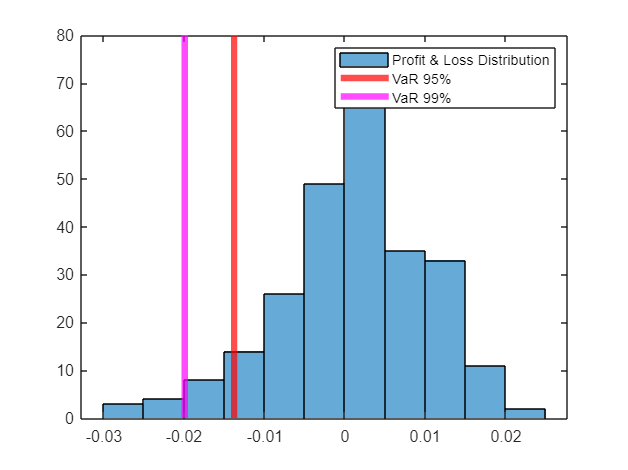

mu = mean(pRet);
std_ = std(pRet);

VaR_95Norm = mu - std_*norminv(ConfLevel(1,1));
VaR_99Norm = mu - std_*norminv(ConfLevel(1,2));

ES_95Norm = mean(pRet(pRet<VaR_95Norm));
ES_99Norm = mean(pRet(pRet<VaR_99Norm));

figure;
histogram(pRet);
hold on
xline(VaR_95Norm, 'LineWidth', 4, 'Color','r')
xline(VaR_99Norm, 'LineWidth', 4, 'Color','m')
legend('Profit & Loss Distribution', 'VaR 95%', 'VaR 99%')

**Optimization with target value VaR**

fun = @(x) (ExpRet * x);
x0 = rand(size(LogRet,2),1);
x0 = x0./sum(x0);
lb = zeros(1, size(LogRet,2));
ub = ones(1, size(LogRet,2));
Aeq = ones(1, size(LogRet,2));
beq = 1;

pval = 0.05;
tgtVaR = -0.015;

wVaR_95 = fmincon(fun, x0, [], [], Aeq, beq, lb, ub, @(x) nonlinContrVaR(x, LogRet,pval, tgtVaR));


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


**Optimization with ES**

tgtES = -0.05;

wES_95 = fmincon(fun, x0, [], [], Aeq, beq, lb, ub, @(x) nonlinContrES(x, LogRet,pval, tgtES));


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


**Equity Comparison**